# An example of pRF model fitting

Denis Schluppeck, University of Nottingham

[@schluppeck](https://twitter.com/schluppeck)

2019-03-20

## Background

Load in an example stimulus. Information about the stimulus is stored in this `struct`. The `im` field essentially contains a little video of the stimulus aperture (white, where there was a stimulus; black where not).

load('pRFStimImage_example.mat');
stimImage = pRFStimImage;
% make sure all data are "double"
stimImage.im = double(stimImage.im);

and look at it unwrapped in time (as a `montage`). Make sure to permute x and y...

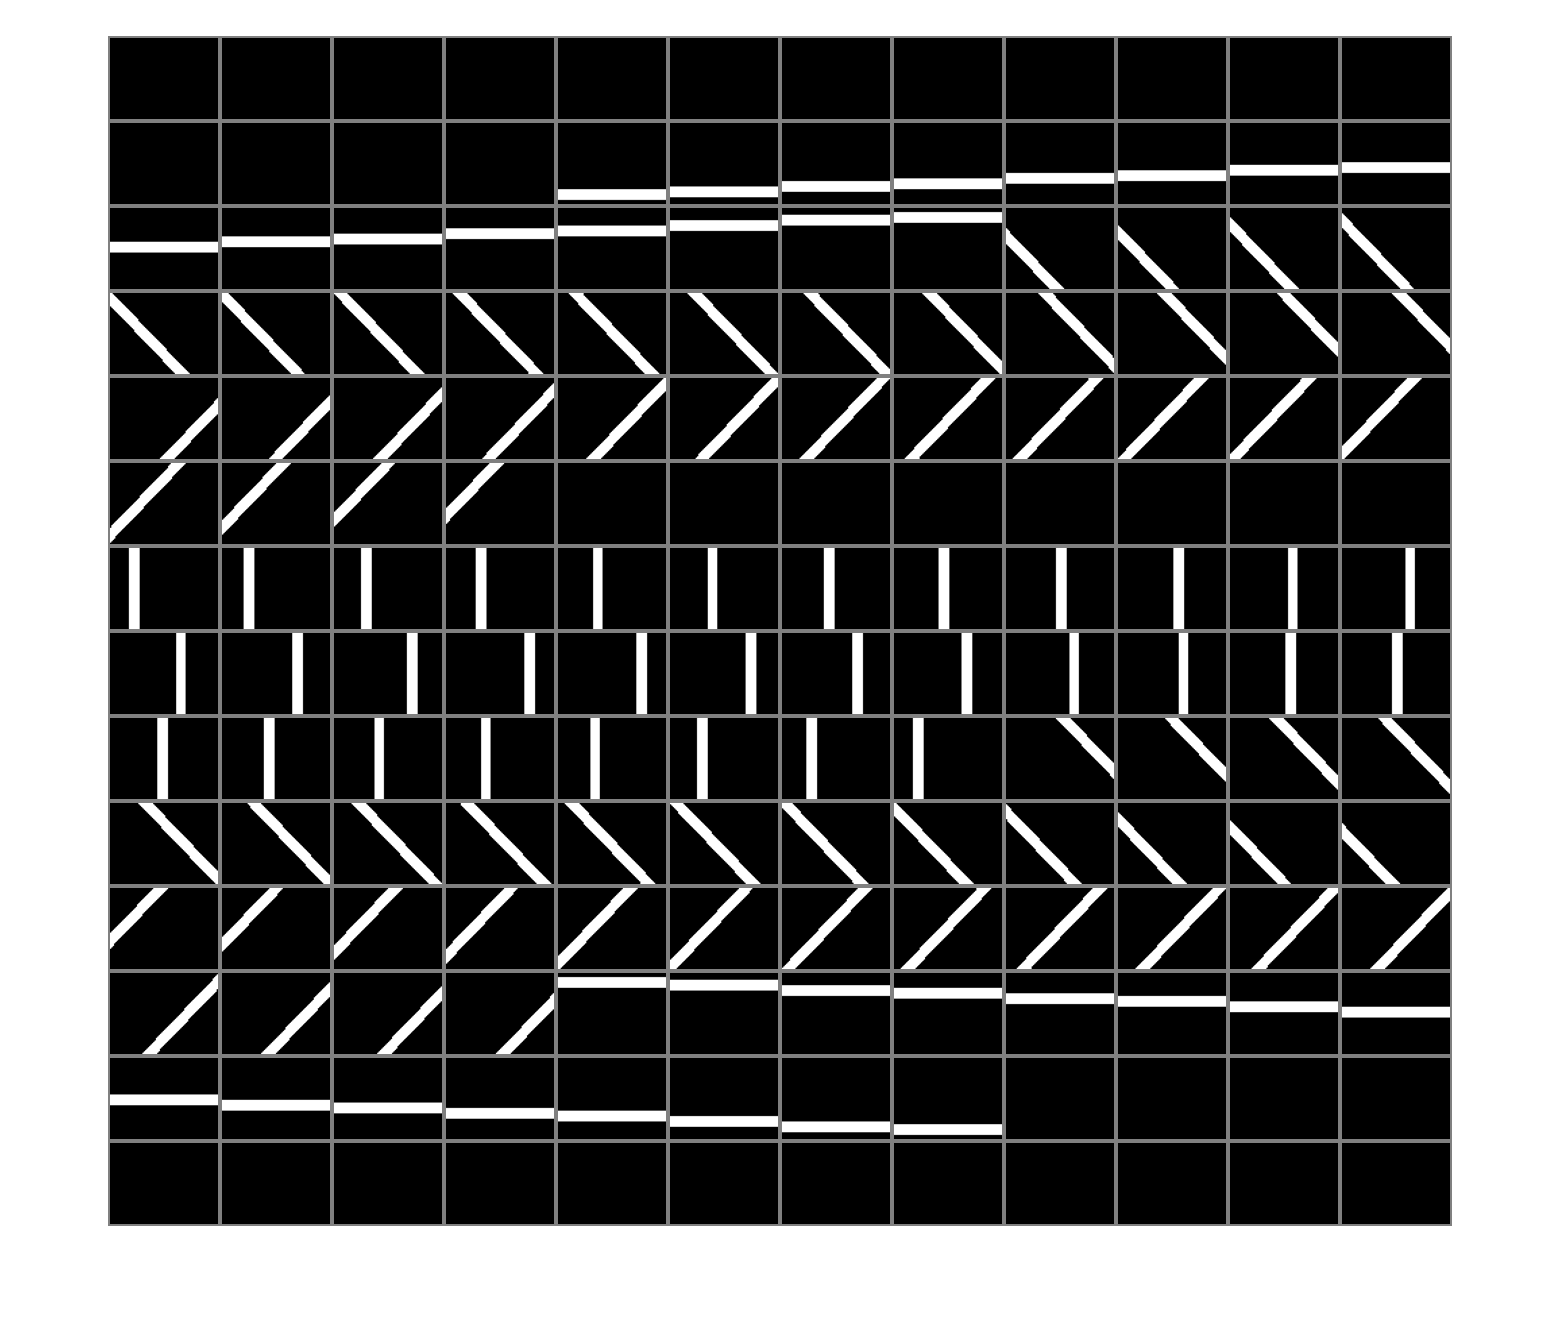

figure
montage(permute(stimImage.im, [2,1,3]), ...
    'BorderSize', [2,2], ...
    'BackgroundColor',[1,1,1]*0.5)

Can also export an image of this for reports or similar:

## Example of a population receptive field (pRF)

The following makes use of some functions in the `mgl` toolbox, so make sure this is on the path. What's on the x` and `y axes can be a bit confusing, but essentially this is a description of the area of visual space that we think a particular voxel cares about – the **population receptive field. This is** interactive!

% vectors
x = stimImage.x(:,1,1);
y = squeeze(stimImage.y(1,:,1));

% mesh versions
mx = stimImage.x;
my = stimImage.y;

Adjust sliders in following so see how the parameters affect the pRF (the "region of visual space that drives the respons.e")

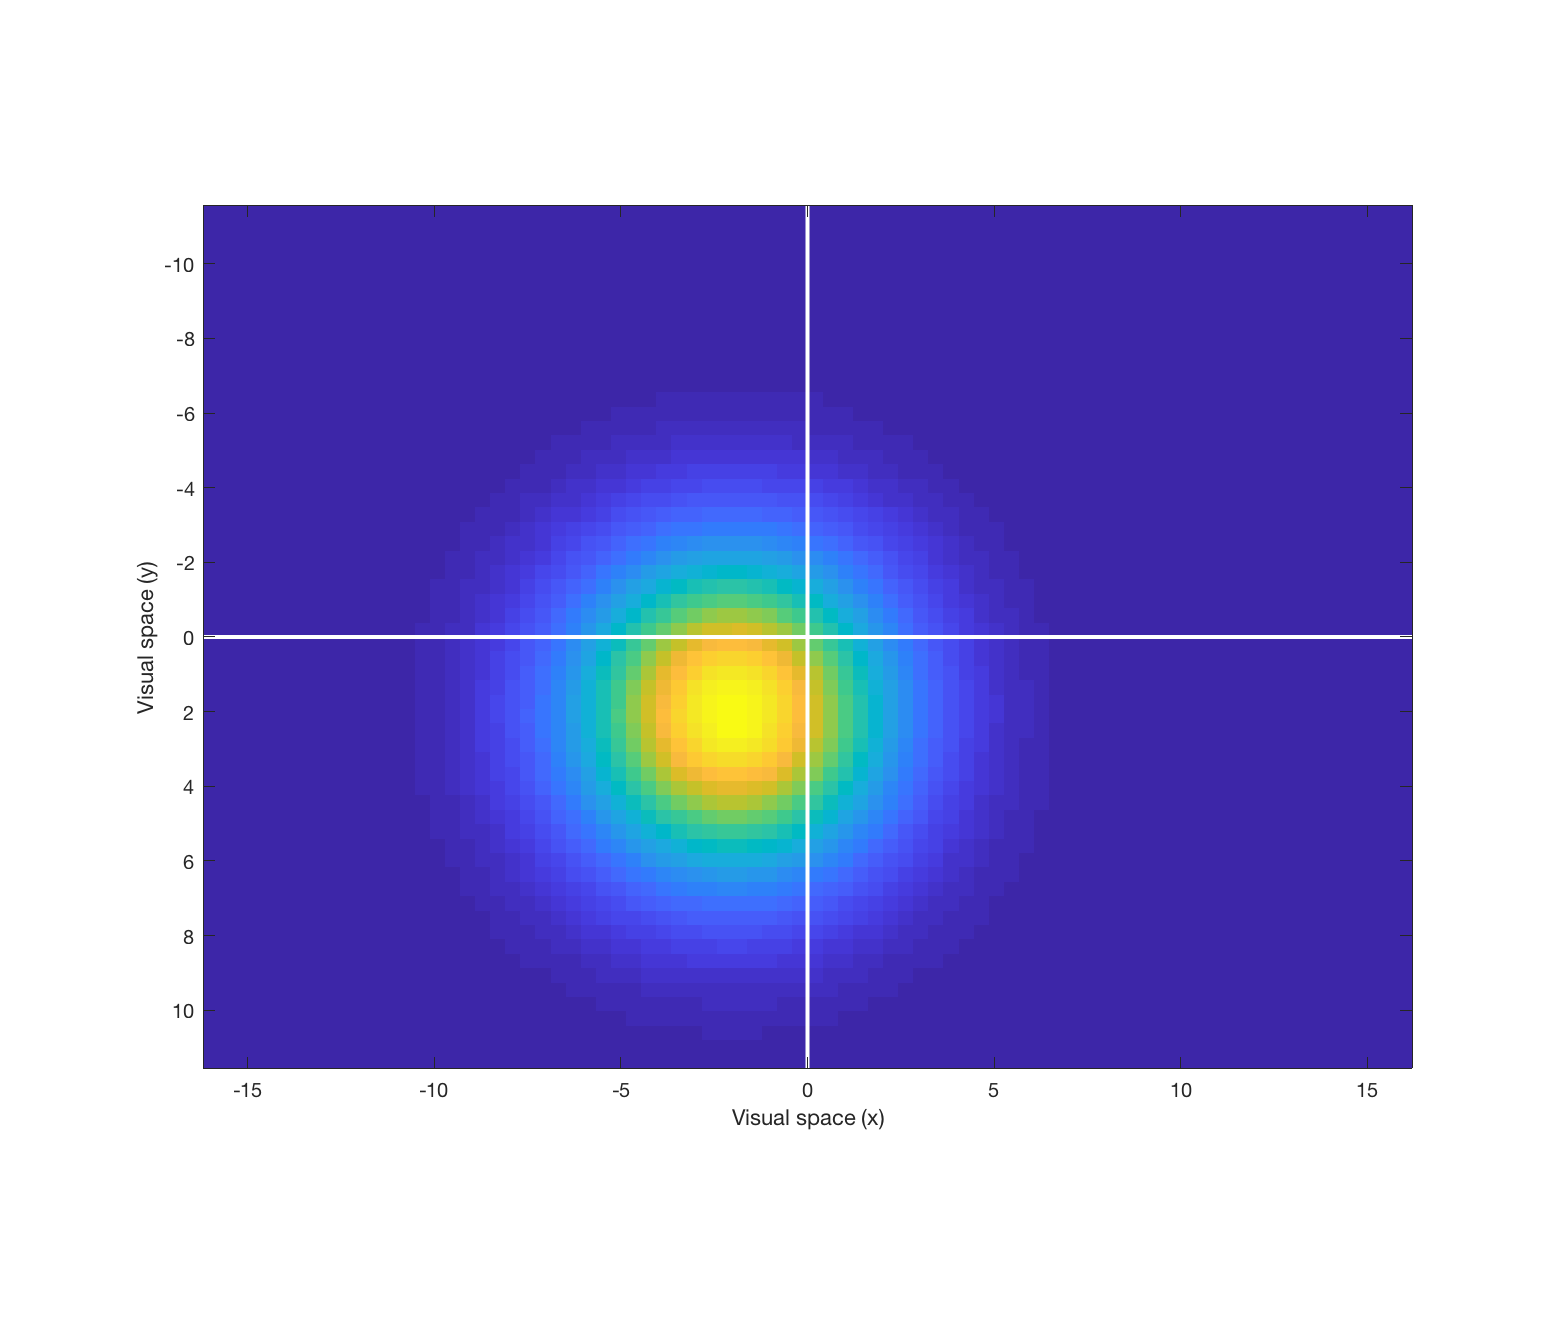

x0 = -2;
y0 = 2;
sigma_xy = 3;

% calculate
p = [x0, y0, sigma_xy];
pRFhat = mgauss(p, mx, my);

% display
imagesc(x,y,permute(pRFhat, [2 1]))
hold('on')
line([0,0], get(gca,'ylim'),'color','w', 'linewidth',2);
line(get(gca,'xlim'),[0,0],'color','w', 'linewidth',2);
axis('image')
colormap(parula())
xlabel('Visual space (x)');
ylabel('Visual space (y)');

## How would a pRF respond to the stimulus?

To calculate how a pRF of this current, example shape (described by $\hat{\text{pRF}}$ or `pRFhat`) would respond, we can multiply each frame of the stimulus by our current estimate / guess of the population receptive field – `pRFhat –` and sum up the responses.

## Two different ways to calculate

If you look inside the function `calculate_prf_response()`, you can see two different implementations of the same idea. One uses a loop – this should be pretty easy to understand: for each frame in the "video", do the calculation.

disp('looping (slow but easier to read?)')

looping (slow but easier to read?)


tic
responseLoop = calculate_prf_response(stimImage,pRFhat, 'loop');
toc

Elapsed time is 0.014574 seconds.


The second way is trickier to grok  – but quite a lot faster to calculate. Reshape the spatial dimension of the stimulus into one big long vector (ie. string all the pixels in the stimulus into one big long thing of length `nx*ny`), do the same for the `pRFhat` and use a simple dot produce (linear algebra) to calculate the response.


$$\mathbf{R_t} = \mathbf{\text{stimulus}_{xy,t}^{T}}\cdot\mathbf{\text{pRF}_{xy}}$$


disp('reshape version (fast)')

reshape version (fast)


tic
response = calculate_prf_response(stimImage,pRFhat, 'reshape');
toc

Elapsed time is 0.007339 seconds.


Assert than both methods do the same – you can look at the difference (sum of squares): it should be very small because both ways ultimately do the same thing:

fprintf('Difference in methods (numerical):')

Difference in methods (numerical):

sum((response-responseLoop).^2)

ans = 2.3644e-25

## Now look at the pRF response

We can now plot the resulting timecourse `response`, which is the predicted response of a whole bunch of neurons that only care about the part of visual space described by `pRFhat`.

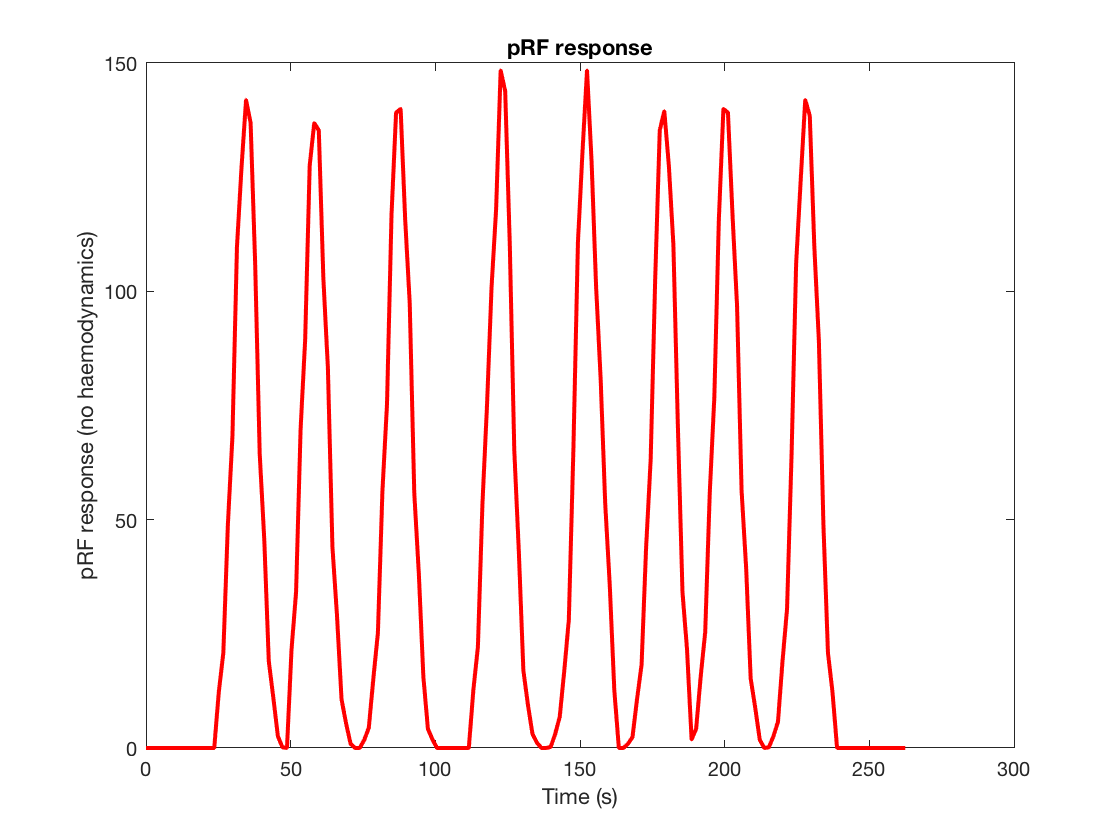

figure
plot(stimImage.t, response, 'r', 'linewidth',2)
xlabel('Time (s)')
ylabel('pRF response (no haemodynamics)')
title('pRF response')

## Thinking about haemodynamics

next step: convolve this response with an HRF shape to get an estimate of an actual fMRI response that we'd expect to see. The function `calculate_prf_response() `is written in such a way that you provide an HRF as an additional input argument, it returns the HRF-convolved version.

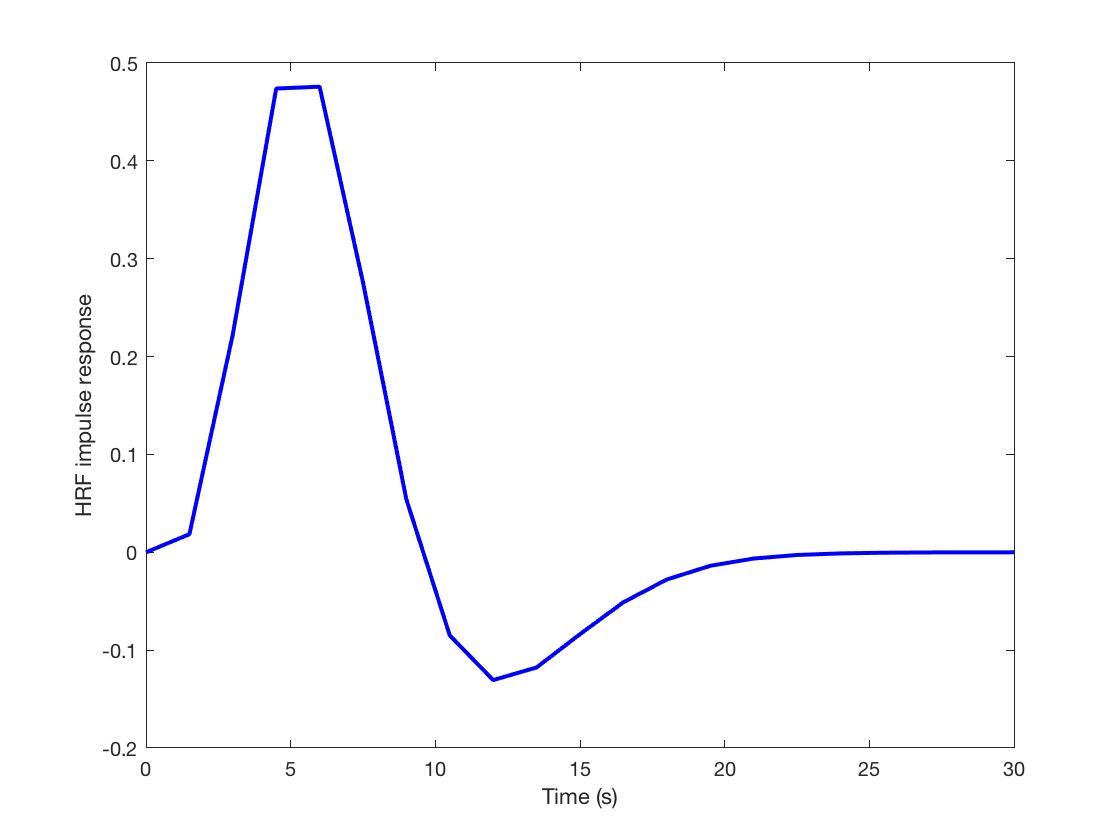

TR = 1.5;
t_hrf = 0:TR:30;
hrf = fmribHRF(t_hrf);
plot(t_hrf, hrf, 'b', 'linewidth',2)
xlabel('Time (s)');
ylabel('HRF impulse response')

With this shape of the haemodynamics (assumed for now, but could also be made part of the fitting), we can now calculate the expected fMRI response:

% note: we also give hrf as input, so get the 
% HRF convolved version back here:
response_hrf = calculate_prf_response(stimImage, ...
    pRFhat, 'reshape', hrf);

Plot both the pRF and functional MRI version of it in one figure to show the differences:

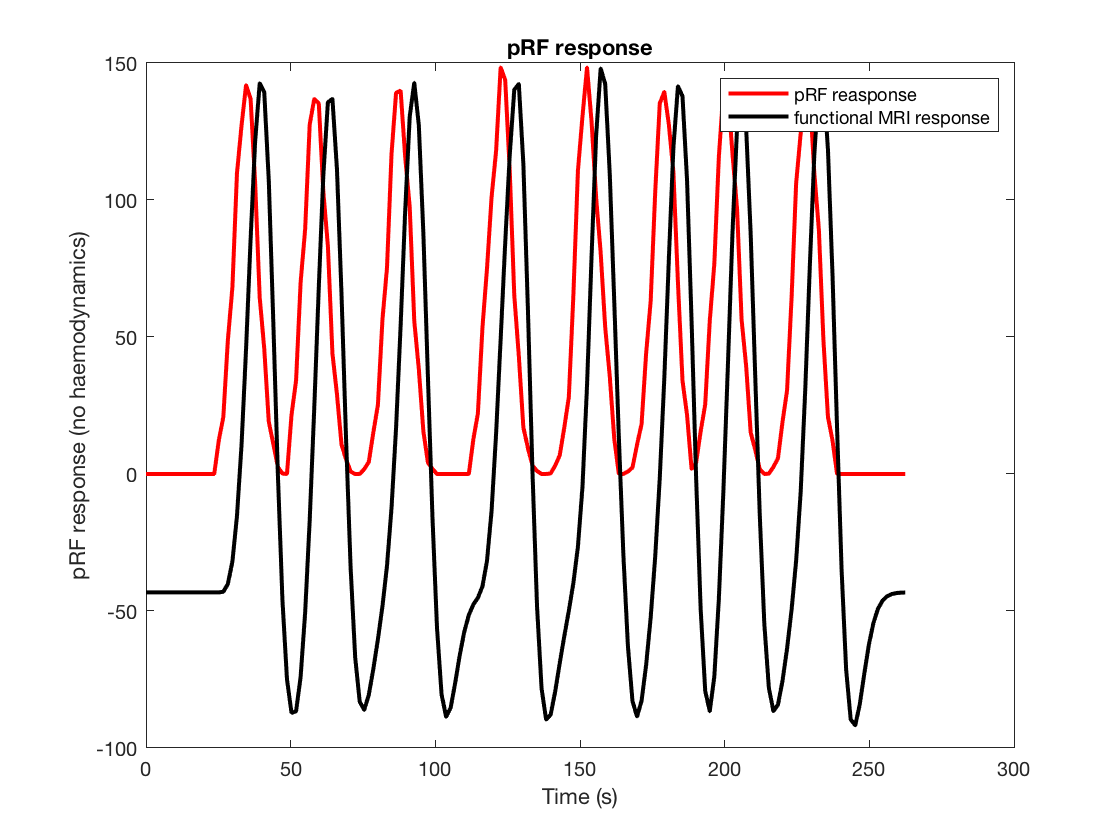

h(1) = plot(stimImage.t, response, 'r', 'linewidth',2);
hold on
h(2) = plot(stimImage.t, response_hrf, 'k', 'linewidth',2);
xlabel('Time (s)')
ylabel('pRF response (no haemodynamics)')
title('pRF response')
legend(h, 'pRF reasponse', 'functional MRI response');

A closure (anonymous function) that calculates response based on a simple set of parameters... this is a function of only the pRF shape:

calculate_with_p = @(p) p(4).*calculate_prf_response(stimImage, ...
    mgauss(p, mx, my), ...
    'reshape', hrf);

## What about actual data?

To find out what the best parameter choices` theta =[x0, y0, sigma_x, sigma_y] `are, we need to optimize (minimize the error between a model prediction for a particular choice of `theta` and the data.

Let's load in a timseries (from scan #8, voxel `[10, 31, 18]` in the dataset from JG's excellent tutorial on his implementation: [http://gru.stanford.edu/doku.php/mrTools/tutorialsprf)](http://gru.stanford.edu/doku.php/mrTools/tutorialsprf))

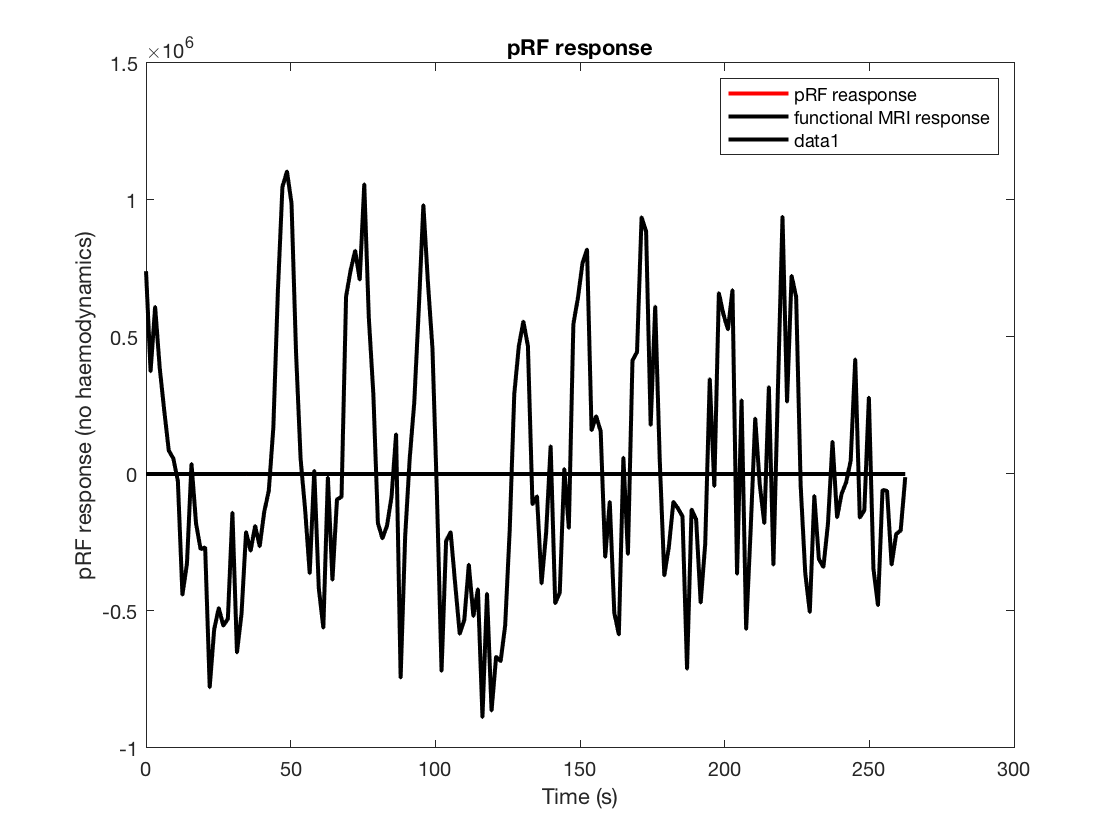

load('tSeries_10_31_18.mat', 'tSeries')
plot(stimImage.t, tSeries, 'k', 'linewidth',2);

## Putting this together:

Now, let's see how changes in the pRF parameter lead to differences in the functional imaging response – more directly without the intermediate visualisations. **Drag around the sliders to see how the model response changes.**

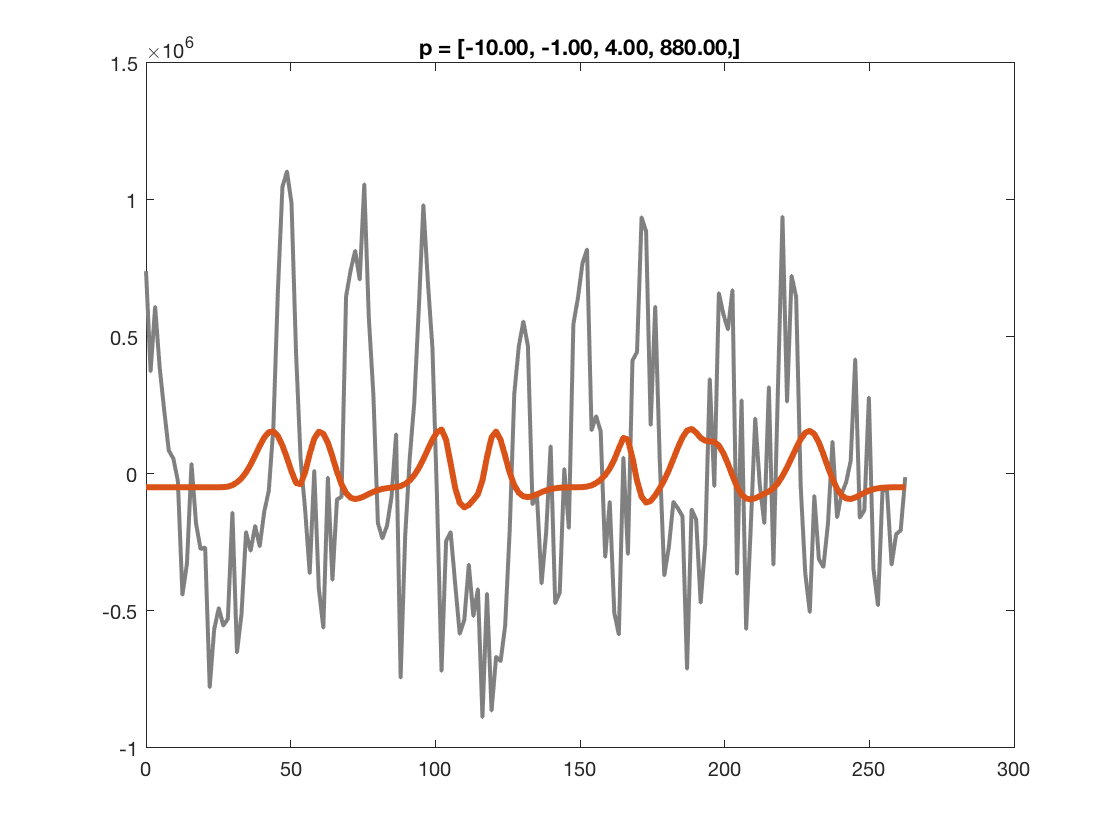

x0 = -10;
y0 = -1;
sigma_xy = 4;
amp = 880;

% calculate (also include AMPLITUDE...)
p = [x0, y0, sigma_xy, amp];

clf
R = calculate_with_p(p); 
plot(stimImage.t, tSeries, 'color', [1,1,1]*0.5, ...
    'linewidth',2);
hold('on')
plot(stimImage.t, R, 'linewidth',3)
title(sprintf('p = [%.2f, %.2f, %.2f, %.2f,]',p))

## Actual fitting

Dragging sliders by hand makes for a nice demonstration of how parameter choices chang the model output. The real aim of the analysis, however, is to find the optimal parameter choices pHat, that minimise some loss between the model and data. Least squares (the L2 norm) is a good and commonly used choice.

There are many ways to do the parameter searching, optimisation. But an easy to understand & teach way is to use `lsqnonlin().` Adapting the example in the help for that function:

ydata = tSeries;             % example ydata     
p0 = [-3.0, -3.0, 1.0, 10000]; % starting vals
fitFunc = @(p) calculate_with_p(p) - ydata;
lb = [-inf, -inf, 0, 1];
ub = +inf(1,4);

pHat = lsqnonlin(fitFunc, p0, lb, ub)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



pHat = 	1.0e+03 *

    0.0019   -0.0065    0.0030    4.3505


Now feed those parameters back into our function to see what the best fitting model shape is:

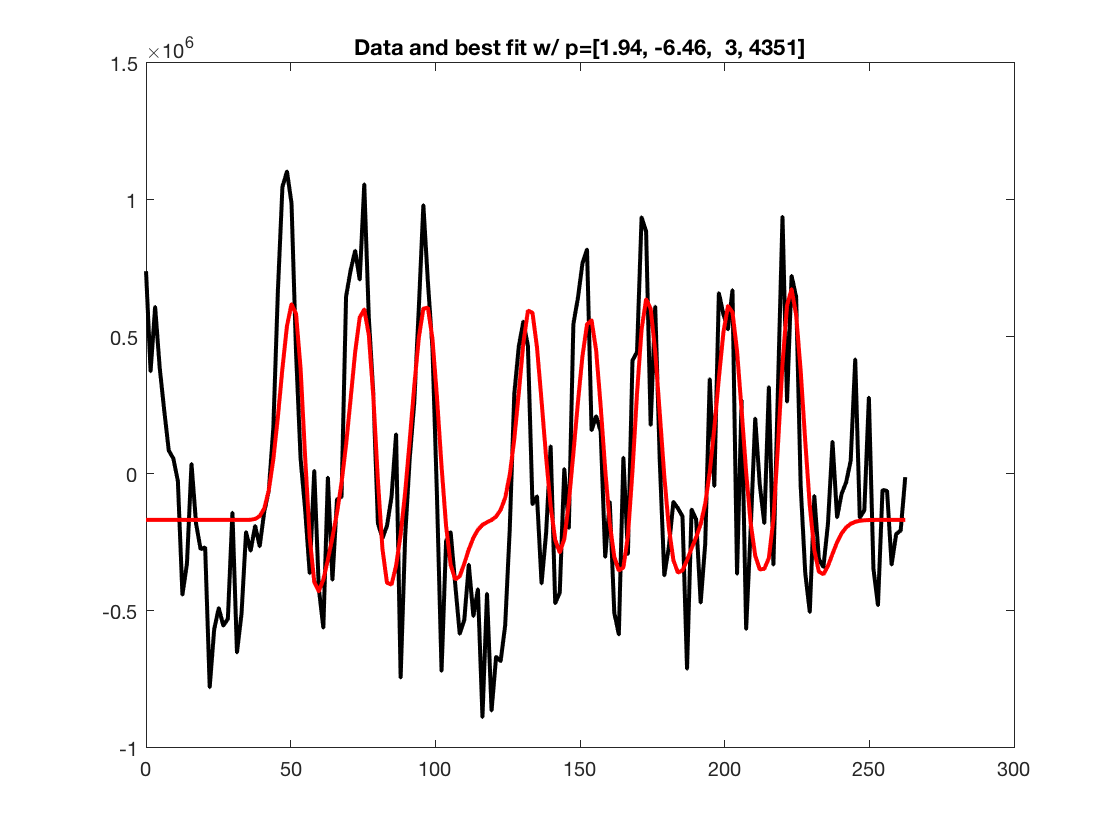

tSeriesHat = calculate_with_p(pHat);

figure
p_ = plot(stimImage.t, tSeries, 'k-', stimImage.t, tSeriesHat, 'r-');
set(p_, 'LineWidth',2)
% the axis limits
axLimits = cell2mat(get(gca, {'xlim', 'ylim'}));
title(sprintf('Data and best fit w/ p=[%.2f, %.2f, %2.f, %.0f]',pHat))

The residuals are simply the difference between model and data:

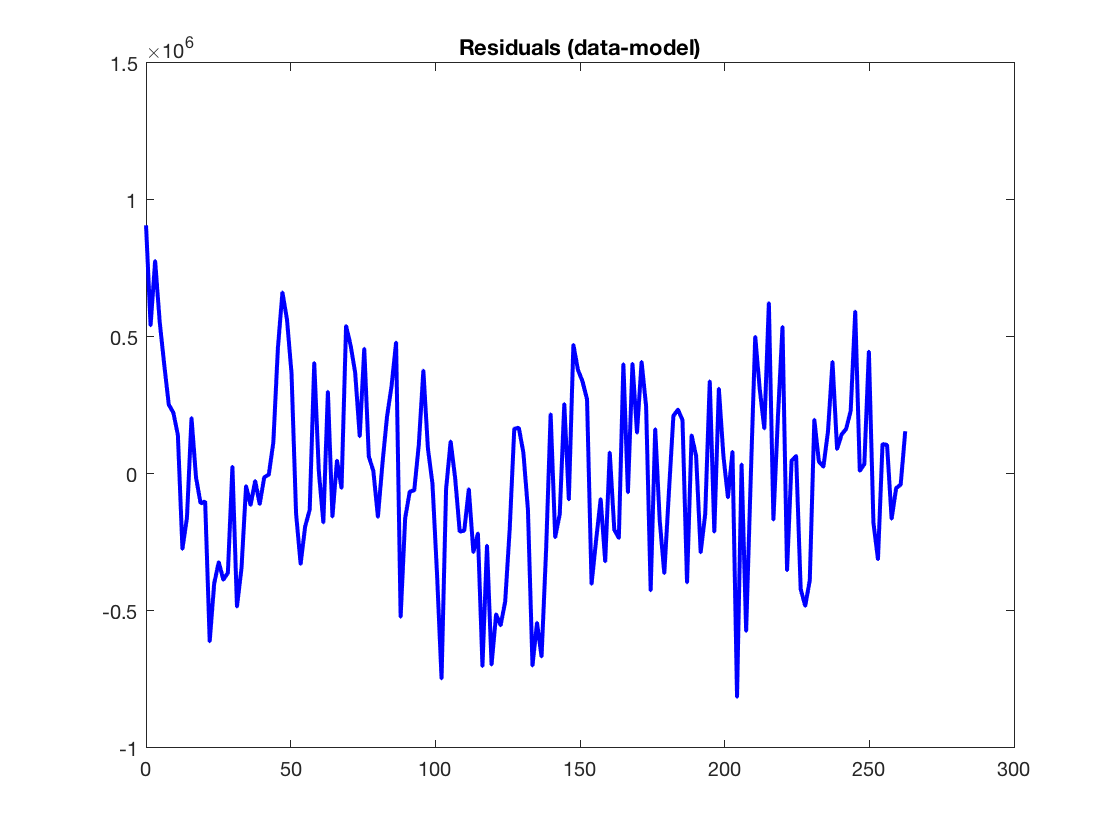

plot(stimImage.t, tSeries - tSeriesHat, 'b', 'LineWidth',2);
% use the same axis limits
axis(axLimits)
title('Residuals (data-model)')

For a larger data set, these calculations are done voxel-wise across a whole ROI or the complete imaging volume. This takes time, but there is parallelism at the level of data – so Justin's implementation actually makes use of a `parfor` loop to do batches of voxels in parallel.

Ideas, suggestions of how to make this better. Let me know.

## Notes and references

Tested with `MATLAB Version: 9.4.0.813654 (R2018a)` on macOS. If you find errors, typos, better ways of doing things, [submit and issue on the github repo](https://github.com/schluppeck/prf-explainer/issues).

- Serge Dumoulin's homepage (original paper, software) – [http://www.spinozacentre.nl/dumoulin/](http://www.spinozacentre.nl/dumoulin/)

- Brian Wandell's homepage – [https://web.stanford.edu/group/vista/cgi-bin/wandell/](https://web.stanford.edu/group/vista/cgi-bin/wandell/)

- Justin Gardner's homepage – [http://gru.stanford.edu/doku.php/shared/home](http://gru.stanford.edu/doku.php/shared/home)

- [http://gru.stanford.edu/doku.php/mrTools/tutorialsprf](http://gru.stanford.edu/doku.php/mrTools/tutorialsprf) – mrTools implementation (and tutorial for how to use)